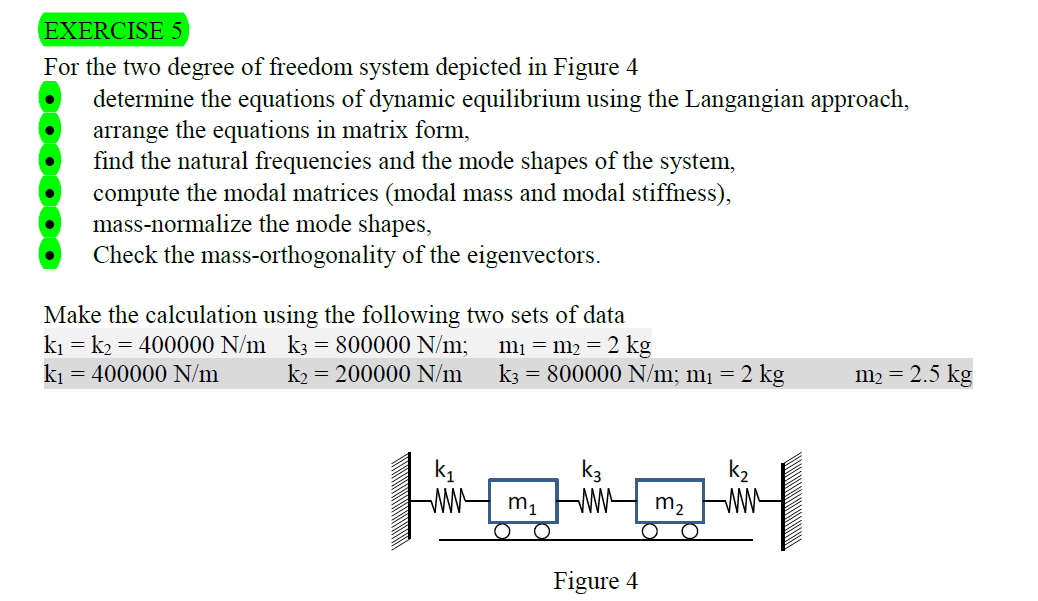

clear all
clc

m1=2;
m2=m1;



k1=400*10^3;
k2=k1;
k3=800000;

M=[m1 0;0 m2];
K=[k1+k2 -k2;-k2 k2+k3];


%solve the eigenproblem det(K-w^2*M)=0, obtaining two values of w^2
[phi,w]=eig(K,M);

wn1=sqrt(w(1,1))

wn1 = 525.7311

wn2=sqrt(w(2,2))

wn2 = 850.6508



%Compute modal mass, modal stiffness and modal forces
Mm=phi(1:2,1)'*M*phi(1:2,1)

Mm = 1.0000

Km=phi(1:2,1)'*K*phi(1:2,1)

Km = 2.7639e+05

phi_Mnorm=phi(1:2,1)/sqrt(Mm)/-0.6015

phi_Mnorm =     1.0000
    0.6180




phi_Mnorm'*Mm*(phi(1:2,2)/sqrt(Mm)/-0.6015)

ans = -1.1102e-16


phi

phi =    -0.6015   -0.3717
   -0.3717    0.6015
